## Standard Distributions

Some distirbution are used so often, that they become part of a standard set of distributions supported by MATLAB. The MATLAB Statistics Toolbox supports a large number of probability distirbutions. Using MATLAB, it becomes quite easy to calculate the probabilty density, cumulative density of these distirbutions, and to sample random values from these distirbuition. The MATLAB documentation lists many more distributions that can be simulated with MATLAB. Using online resources, it is often easy to find support for a number of other common distirbutions. 

## Exercise

- Adapt the MATLAB program to illustrate the Beta $(\alpha, \beta)$ distribution where $\alpha = 2$ and $\beta = 3$. Similarly, show the Exponental( $\lambda$ ) distribution where $\lambda = 2$ 

-  Adpt the MATLAB program aobve to iilustrate the Binomial $(N, \theta)$ distribution where $N = 10 \text{ and } \theta = 0.7$. 

- Write a demonstration program to sample 10 values from a Bernoulli( $\theta$ ) distribution wtih $\theta = 0.3$. Note that the Bernoulli distribution is one of the simplest discrte distributions to simulate. There are only two possible outcomes, 0 and 1. With probability $\theta$, the outcome is 1, and with probability $1 - \theta$m the outcome is 0. In other words, $p(X = 1) = \theta$, and $p(X = 0) = 1 - \theta$, This distribution can be used to simulate outcomes in a number of siturations, such as head or tail outcomes from a weighted coin, correct/incorrect outcomes from true/false questions,etc. In MATLAB, you can simulate the Bernoulli distribtuion using the binomial distribution with $N = 1$. However, for the purpose of this exercies, please write the code needed to sample bernoullis distirbuted values that does not make use of the built-in binomial distribution. 

- It is often useful in simulations to ensure that each replication of the simulation gives the exact same result. In MATLAB, when drawing random valeus from distributions, the values are different every time you restart the code. There is a simple way to "seed" the random number generators to insure that they produce the same sequence. Write a MATLAB script that samples two sets 10 random values drawn from a uniform distrubtion between $[0, 1]$. Use the seeding function between the two sampling steps to demonstrate that the two sets of random values are identical. your MATLAB code coud use the following line: `seed = 1; rand('state',seed); randn('state', seed); `

- Suppose we know  from previous research that in a given population, IQ coefficients are normally distributed with a mean of 100 and a standard deviation of 15. Calculate the probability that a randomly drawn person from this population has an IQ geater than 110 but samller tahn 130. You can achieve this using one line of MATLAB code. What does this look like? 

- The Dirichlet distribution is currently not supported by MATLAB. Can you find a MATLAB function, using online resources, that implements the sampling from a Dirichlet distirbution? 

%% Exercise One 
%% parameters
x_min = 0;
x_max = 10; 
n = 100;
alpha = 2;
beta = 3;
lambda = 2;

x = linspace(x_min, x_max, n);
beta_pdf = betapdf(x,alpha, beta);
exponential_pdf = exppdf(x,1/lambda);

subplot(1,2,1);
plot(x, beta_pdf, 'k');
xlabel('x'); ylabel('pdf');
title('Probability Density Function of beta(2,2)');

subplot(1,2,2);
plot(x, exponential_pdf, 'k-');
xlabel('x'); ylabel('pdf');
title('Probability Density Function of exp(2)');

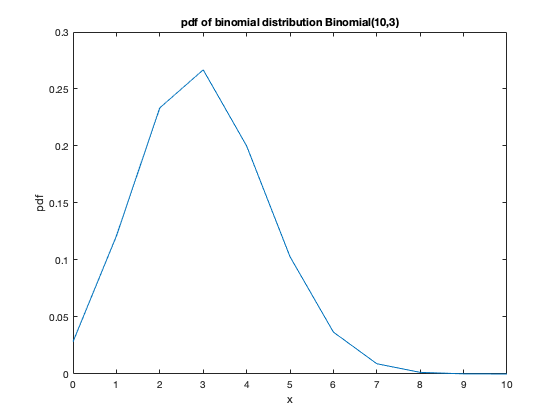

%% Exerciese Two
%% parameters
clc; 
clear;
N = 10;
theta = 0.3; 
x_min = 0;
x_max = 10; 
n = 1000000000;

x = x_min:x_max;
probability_binomial = binopdf(x, N, theta);
subplot(1,1,1);
plot(x, probability_binomial);
xlabel('x'); ylabel('pdf');
title("pdf of binomial distribution Binomial(10,3)");

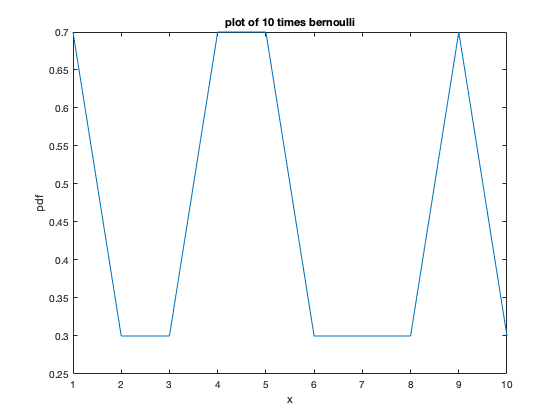

%% Exerciese Three
clc; 
clear;
%% parameters
values = 1; 
N = 1; 
theta = 0.3;
probability_bernoulli = zeros(10,1);
for i = 1:10
    probability_bernoulli(i) = binopdf(round(rand(1)), N, theta);
end
plot(1:10, probability_bernoulli);
xlabel('x'); ylabel('pdf');
title("plot of 10 times bernoulli");

## Exerciese Four



clc; 
clear;
%% parameters
seed = 1; 